addpath('../../../shapelets/');
addpath('../../../shapelets/shapelet_space_matlab/');
load underreporting_facts.mat


% T = maxt; T = 104; horizon = 100;
% thisday = T;
nl = 2; urep = 1./un_mid;
ag_popu_frac = pop_by_age./sum(pop_by_age, 2);
compute_region = popu > -1;
var_frac_all = zeros(ns, 2, T);
var_frac_all(:, 1, :) = 1;

nw = ceil((T+horizon)/1)+1;
waned_impact = zeros(nl, nw, nw, ag);
tdiff_matrix = (0:1:(nw-1))' - (0:1:(nw-1));
tdiff_matrix(tdiff_matrix <= 0) = -Inf;

ag_wan_lb = 0*ones(ag, 1);
ag_wan_param = 50*ones(ag, 1);
vacc_effi_60 = 0.99*ones(ag, 1);
week_at_effi = 30;

for idx = 1:ag
    for ll=1:nl
        [k, theta] = gamma_param_med(ag_wan_param(idx), ag_wan_lb(idx), vacc_effi_60(idx), week_at_effi);
        waned_impact(ll, :, :, idx) = (1-ag_wan_lb(idx)).*gamcdf(tdiff_matrix, k, theta);
    end
end
waned_impact(isinf(waned_impact)) = 0;
waned_impact(isnan(waned_impact)) = 0;

un_ag = ones(ag, 1);
un_3d = prod_2w3(urep, hosps_3D_s(:, 1:T, :));
un = squeeze(sum(un_3d, 3));
ag_case_frac = un_3d./(1e-30 + sum(un_3d, 3));
age_transit = 1./(52*(age_groups_r - age_groups_l));

all_data_vars0 = cell(nl, 1);
all_data_vars = zeros(ns, nl, thisday);
k = 2; jp = 1;
dd = un;
un_fact = 1;

for l=1:nl
    variant_fact = squeeze(var_frac_all(:, l, :));
    data_var_s = cumsum(dd.*(variant_fact), 2);
    all_data_vars0{l} = data_var_s;
    all_data_vars(:, l, :) =  data_var_s;
end


[all_betas, all_cont, fC,immune_infec, ALL_STATS, ~, rel_booster_effi] = Sp_multivar_beta_escape(all_data_vars, 0, popu, k, this_alpha, ...
        jp, 1, ag_case_frac, ag_popu_frac, waned_impact, all_boosters_ts, [], ...
        [], [], [], 1, 1, [], [], age_transit);

rate_change = ones(ns, horizon);
base_infec = zeros(ns, T);

[infec, deltemp, immune_infec1, ALL_STATS_new, protected_popu_frac] = Sp_multivar_pred_escape(all_data_vars, 0, ...
    all_betas, popu, k, horizon, jp, 1, base_infec, rate_change, ...
    ag_case_frac, ag_popu_frac, waned_impact, all_cont, 0, ...
    all_boosters_ts, [], [], [], ALL_STATS, 1, 1, [], [], age_transit);

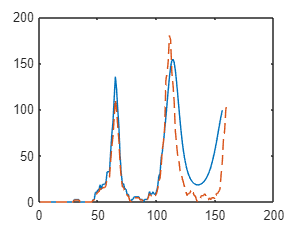

close all;
deltemp = deltemp_all{10};
%figure;
cid = 1; gg = 1;
plot(prod_2w3(1./urep(cid, gg), squeeze(deltemp(cid, 1, :, gg))));
hold on;
plot(squeeze(hosps_3D_s(cid, :, gg)), '--');

## Compute errors

dtw_norm_err = zeros(ns, ag);
for gg=1:ag
    for cid = 1:ns
        preds = prod_2w3(1./urep(cid, gg), squeeze(deltemp(cid, 1, :, gg)));
        gt = squeeze(hosps_3D_s(cid, :, gg));
        T_end = min(length(preds), length(gt));
        t1 = gt(T:T_end); t1 = t1(:)';
        t2 = preds(T:T_end); t2 = t2(:)';
        dtw_norm_err(cid, gg) = dtw_cons_md(t1, t2, 5)/max(gt(T:T_end))^2;
    end
end
median(median(dtw_norm_err))

ans = 27.5471

## Test Retrospective Sims

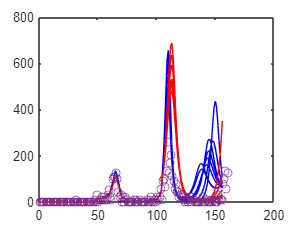

close all;
cid = 1; gg = 1;

fixed_params = [-1 0.85 -1 -1 -1];
var_param_idx = 1;

good_ones = (dtw_med_error < quantile(dtw_med_error, 0.25));

idx = ones(size(scen_list, 1), 1) & good_ones;
for j = 1:size(scen_list, 2)-1
    if fixed_params(j) > -1
        idx = idx & (scen_list(:, j) == fixed_params(j));
    end
end

cc = {'b', 'r', 'g', 'k', 'y'};
var_params = unique(scen_list(:, var_param_idx));

figure;
for j = 1:length(var_params)
    idx1 = find(idx & scen_list(:, var_param_idx)==var_params(j));
    for jj=1:length(idx1)
        preds = prod_2w3(1./urep(cid, gg), squeeze(deltemp_all{idx1(jj)}(cid, 1, :, gg)));
        plot(preds, cc{j});
    hold on
    end
    
end

gt = squeeze(hosps_3D(cid, :, gg));
plot(gt, 'o')

## Test projections

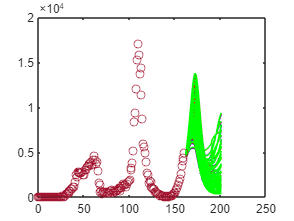

close all;
cid = 13; gg = 1:8;

fixed_params = [-1 -1 -1 -1 -1];
var_param_idx = 2;

good_ones = ones(size(scen_list, 1), 1);

idx = ones(size(scen_list, 1), 1) & good_ones;
for j = 1:size(scen_list, 2)-1
    if fixed_params(j) > -1
        idx = idx & (scen_list(:, j) == fixed_params(j));
    end
end

cc = {'b', 'r', 'g', 'k', 'y'};
var_params = unique(scen_list(:, var_param_idx));

figure;
for j = 1:length(var_params)
    idx1 = find(idx & scen_list(:, var_param_idx)==var_params(j));
    for jj=1:length(idx1)
        i = idx1(jj);
        preds = squeeze(sum(net_hosp_C(i, cid, :, gg), 4));
        plot(T+1 : T+horizon, preds, cc{j});
        hold on
    end
end

gt = squeeze(sum(hosps_3D(cid, :, gg), 3));
plot(gt, 'o')